# Time Series

A time series are sequences of values measured over time. It can be tempreture of a city over days in a year or changes in electrical potentials measured from sclap. 

**Simulating time series:**

Sine waves serve as the fundamental components for  frequency and time-frequency analyses. A sine wave can be generated by three key parameters: frequency (representing the speed of the sine wave), amplitude (indicating the height or energy level of the sine wave), and phase (determining the timing of the sine wave).

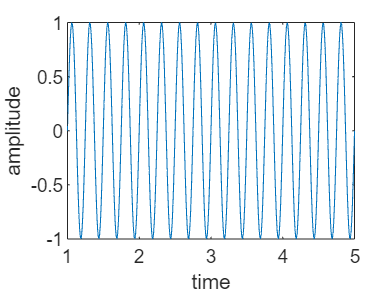

time= 1:.01:5;
frequency = 4;
amplitude = 1;
phase = 0;

sinewave = amplitude * sin(2*pi*frequency*time + phase);

figure
plot(time,sinewave)
xlabel('time')
ylabel('amplitude')

Complex waves:

Multiple sine waves can be summed to create a more complex wave.

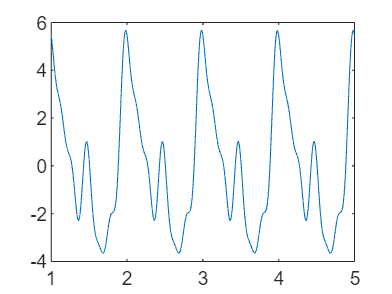

time = 1:.01:5;
frequencies = [.5,1,2,4,6];
amplitudes = [4,3,2,1,.5];
phases = [pi/6,pi/3,pi/2,2*pi/3,pi];

comSinWave = 0;

for i = 2:length(frequencies)

    comSinWave = comSinWave + amplitudes(i) * sin(2*pi*frequencies(i)*time + phases(i));
end

figure
plot(time,comSinWave)

**Adding noise:**

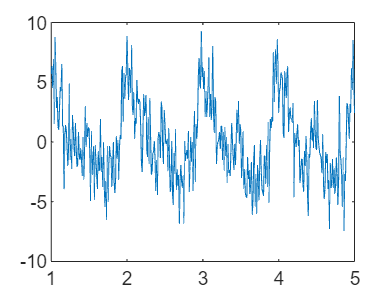

comSinWave = comSinWave + 2*randn(size(comSinWave));

figure
plot(time,comSinWave)

**Stationary and non-stationary time series**  

In a stationary time series, statistical properties, such as mean,variance and autocorrelation, remain constant over time. Otherwise the time series is considered as non-stationary. Stationary time series are easier to analyze because the statistical measures remain consistent, allowing for more reliable predictions. A Gaussian white noise is considered as an stationary time series.

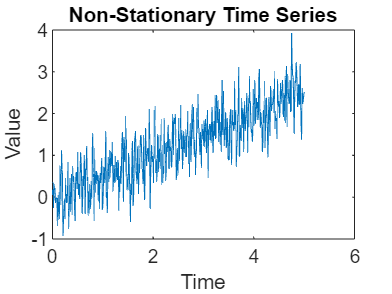

% Non-Stationary Time Series Example
time = 0:.01:5;

% Generate a non-stationary time series with a trend
trend = .5 * time; % Linear trend
noise = 0.5 * randn(1, length(time)); % Random noise
nonStationarySeries = trend + noise;

figure;
plot(time, nonStationarySeries);
title('Non-Stationary Time Series');
xlabel('Time');
ylabel('Value');

Stationarity plays a crucial role in time series analysis since numerous techniques, such as the Fourier transform, rely on the assumption of stationary data. While violations of stationarity don't necessarily render analyses incorrect, they can complicate result interpretation. Fortunately, there exist various simple techniques to transform non-stationary time series into stationary ones, such as taking deravative or applying filters.

# Linear and Time Invariance Systems (LTI System)

**Linearity** is associated with two key properties: superposition and homogeneity.

**Superposition**: This means that if ***y*****1(*****t*****)** is the system response to input ***x*****1(*****t*****)** and *y*2(*t*) is the response to input ***x*****2(*****t*****)**, then the response to the sum of these inputs ***x*****1(*****t*****)+*****x*****2(*****t*****)** is equal to the sum of the individual ***y*****1(*****t*****)+*****y*****2(*****t*****)**

                                            x1(t) ------------> y1(t)

                                            x2(t) ------------> y2(t)

                                x1(t)  + x2(t) ------------> y1(t) +y2(t)

**Homogeneity** (Scaling): A linear system also exhibits homogeneity, meaning that scaling the input signal by a constant scales the output signal by the same constant. If ***y*****(*****t*****)** is the response to ***x*****(*****t*****)**, then the response to ***a*****⋅*****x*****(*****t*****) is *****a*****⋅*****y*****(*****t*****)** for any constant .

                                            x(t) ------------> y(t)

                                        a* x(t) ------------> a* y(t)

A system is considered **time-invariant** if its behavior or characteristics do not change over time. In other words, the system's response to a given input remains constant regardless of when the input is applied. The system's output remains unchanged when the input is delayed or advanced in time. Mathematically, if ***y*****(*****t*****)** is the output for an input ***x*****(*****t***), then for a time-invariant system, ***y*****(*****t*****−*****τ*****)** should be the same as the system output for the input ***x*****(*****t*****−*****τ*****)**, where *τ* is a time shift.

**Impulse response**

For an LTI system we can completely characterize the behavoir of the system by giving very simple signals as inputs. We call such input an **impulse input** that is often represented by Dirac delta function, denoted as δ(t) in continuous time or δ[n] in discrete time.The **impulse response **of a system, is the output of the system when the input is an impulse. If we know the impuse response of an LTI system then we can understand how the system behave.

# Convolution

When we know the impulse response of and LTI system it would be easy to determine the reposne to any signal because any input signal can be decomposed into a sum (or integral, in the continuous case) of scaled and shifted impulse function, and the output can be expressed as scaled and shifted inpulsed response. Applying the linearity properties allows you to determine the system's response to any input signal.

**Convolution**, is a mathematical operation that combines the system's impulse response with the input signal to calculate the output signal. Convolution makes the life easier so that for an LTI system we don't need to calculate output for any specific input signal we just need to know input and impulse response of the system.

Mathematically, for a continuous-time system, the relationship between the impulse response h(t) and the system output y(t) to an arbitrary input x(t) can be expressed using convolution:

*                                        y*(*t*) = ∫ *x*(*τ*)⋅*h*(*t*−*τ*) *dτ*

For a discrete-time system, the convolution sum is used:

*                                        y*[*n*] = ∑ *x*[*k*]⋅*h*[*n*−*k*]

**Graphical representation of convolution**

xn = [2,3,-1]; % An arbitrary input signal 


Now we can break it into a weighted sum of shifted impulse function:

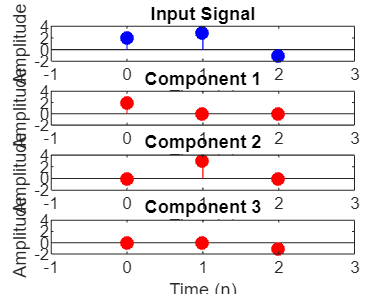

delta = [1 0 0]; % Delta impulse function
x1 = xn.*circshift(delta,0);
x2 = xn.*circshift(delta,1);
x3 = xn.*circshift(delta,2);


% Plot the imput signal and as a weighted sum of shifted impulse function
ax = subplot(4, 1, 1);
stem(0:length(xn)-1, xn, 'b', 'filled');
title('Input Signal');
xlabel('Time (n)');
ylabel('Amplitude');
ax.XLim = [-1, 3];
ax.YLim = [-2, 4];

ax = subplot(4, 1, 2);
stem(0:length(x1)-1, x1, 'r',  'filled');
title('Component 1');
xlabel('Time (n)');
ylabel('Amplitude');
ax.XLim = [-1, 3];
ax.YLim = [-2, 4];


ax = subplot(4, 1, 3);
stem(0:length(x2)-1, x2, 'r', 'filled');
title('Component 2');
xlabel('Time (n)');
ylabel('Amplitude');
ax.XLim = [-1, 3];
ax.YLim = [-2, 4];

ax = subplot(4, 1, 4);
stem(0:length(x3)-1, x3, 'r',  'filled');
title('Component 3');
xlabel('Time (n)');
ylabel('Amplitude');
ax.XLim = [-1, 3];
ax.YLim = [-2, 4];

Let's impulse response of the system h(t) be:

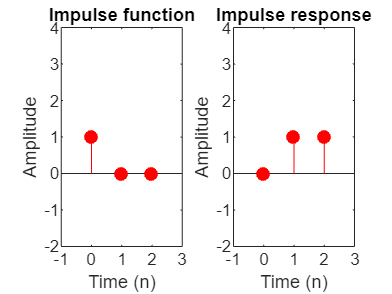

ht = [0 1 1]; % This impulse response takes an impulse input and gives back two impulse with a one step shift forward

ax = subplot(1, 2, 1);
stem(0:length(delta)-1, delta, 'r',  'filled');
title('Impulse function');
xlabel('Time (n)');
ylabel('Amplitude');
ax.XLim = [-1, 3];
ax.YLim = [-2, 4];

ax = subplot(1, 2, 2);
stem(0:length(ht)-1, ht, 'r',  'filled');
title('Impulse response');
xlabel('Time (n)');
ylabel('Amplitude');
ax.XLim = [-1, 3];
ax.YLim = [-2, 4];

What if we change input signal to any arbitrary signal?

inputSignal = [2 1 0 0 0 0] % Usually we add some zeros at the end so that we can shift the signalg easily

inputSignal =      2     1     0     0     0     0


ht = [0 1 1 0 0 0] % impuse response

ht =      0     1     1     0     0     0


We can write it in terms of shifted and scaled sum of impulse function.

inputSignalRec = 2.*circshift(delta,0) + 1 .* circshift(delta,1) + 0 .* circshift(delta,2) % input signal reconstruction

inputSignalRec =      2     1     0


We can use the linearity properties of the system to compute the output. If we scale the impuse input, the impulse response would be shifted and if we scale the impuse input the output would be shifted and if we and if add different inputs, the corresponding outputs should be added to gether.

outputSignal =2.*circshift(ht,0) + 1 .* circshift(ht,1) + 0 .* circshift(ht,2)

outputSignal =      0     2     3     1     0     0


Finally let's check our result with convolution function in matlab.

conv(inputSignal,ht,'full') 

ans =      0     2     3     1     0     0     0     0     0     0     0


outputSignal

outputSignal =      0     2     3     1     0     0


Unerstading convolution is easier from practical point of veiw. In convolution two time series are combined to produce a third one that has charactristics of a third one. We call the time series of interest the signal and the second one the kernel. Operationally to perform convolution in one dimension, first we flip the kernel backward so that last element of the kernel aligns with the first element of the signal and then we comput dot product between signal and kernel.